format compact
close all
clear
clc

15.1 Position-based visual servoing

cam = CentralCamera('default');

principal point not specified, setting it to centre of image plane


P = mkgrid( 2, 0.5, 'pose', SE3(0,0,3) )

P =    -0.2500   -0.2500    0.2500    0.2500
   -0.2500    0.2500    0.2500   -0.2500
    3.0000    3.0000    3.0000    3.0000


T_C = SE3(0,0,0)  %DIFF

 

T_C = 
         1         0         0         0
         0         1         0         0
         0         0         1         0
         0         0         0         1


creating new figure for camera


h =   Axes with properties:

             XLim: [0 1024]
             YLim: [0 1024]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


make axes


p =   445.3333  445.3333  578.6667  578.6667
  445.3333  578.6667  578.6667  445.3333


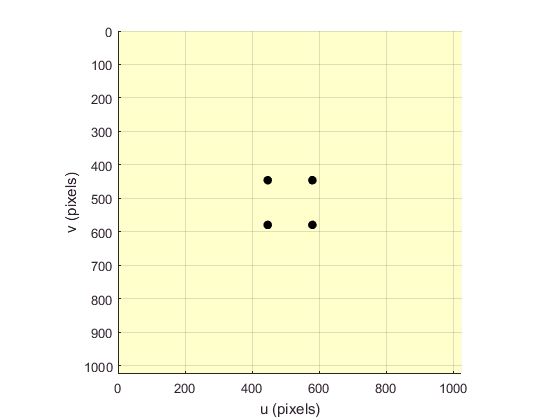

Cd_T_G = SE3(0.1, 0.2, 0.5); %DIFF
p = cam.plot(P, 'pose', T_C)

C_Te_G = cam.estpose(P, p);
T_delta = C_Te_G / Cd_T_G

 

T_delta = 
    1.0000         0   -0.0000      -0.1
         0    1.0000   -0.0000      -0.2
    0.0000    0.0000         1      -0.5
         0         0         0         1


lambda = 0.2;  %DIFF
T_C = T_C .* T_delta.interp(T_C, lambda)

 

T_C = 
         1         0         0     -0.08
         0         1         0     -0.16
         0         0         1      -0.4
         0         0         0         1


T_C0 = SE3(1,1,-3)*SE3.Rz(0.6);
Cd_T_G = SE3(0, 0, 1);
pbvs = PBVS(cam, 'pose0', T_C0, 'posef', Cd_T_G, 'axis', [-1 2 -1 2 -3 0.5])

 
pbvs = 
Visual servo object: camera=default
  200 iterations, 0 history
  P= -0.25       -0.25        0.25        0.25                 
     -0.25        0.25        0.25       -0.25                 
         0           0           0           0                 
  C_T0:   t = ( 1,  1,  -3), R = ( 34.3775deg |  0,  0,  1)    
  C*_T_G: t = ( 0,  0,  1), R = ( 0deg |  0,  0,  0)           


completed on iteration count


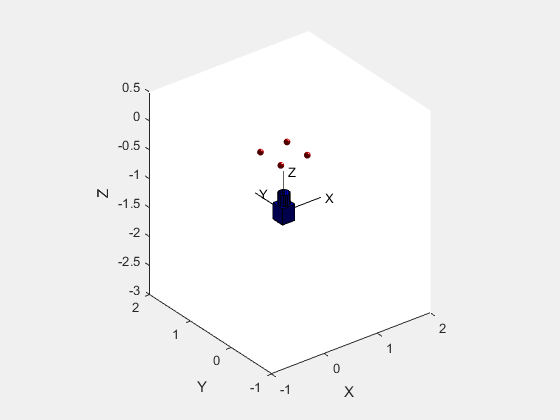

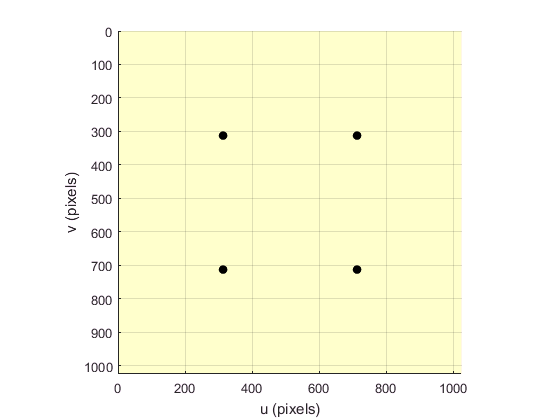

pbvs.run();

ans =   311.9818  311.9902  311.9902  711.9621  711.9621  711.9537  711.9537  311.9818


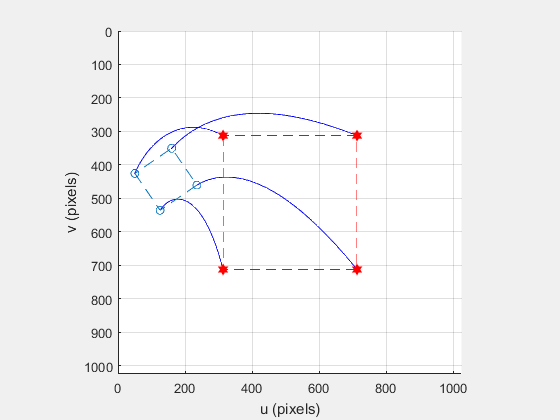

pbvs.plot_p();

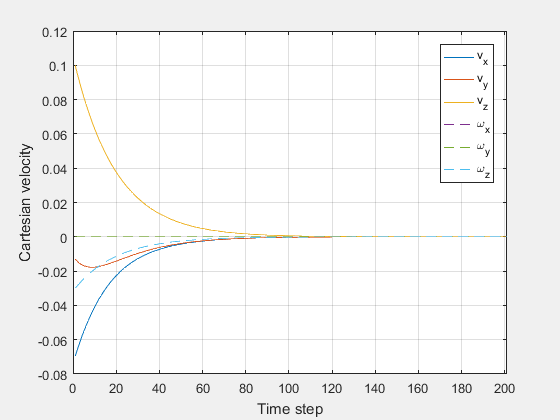

pbvs.plot_vel();

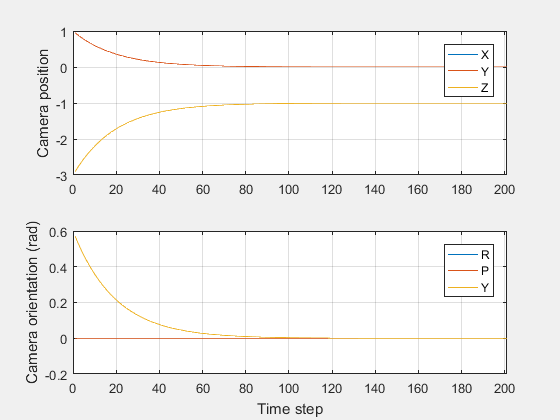

pbvs.plot_camera();

15.2 Image Based Visual Servoing

15.2.1 Camera and image motion

cam = CentralCamera('default');

principal point not specified, setting it to centre of image plane


P = [1 1 5]';
p0 = cam.project(P)

p0 =    672
   672


px = cam.project(P, 'pose', SE3(0.1, 0, 0))

px =    656
   672


(px - p0) / 0.1

ans =   -160
     0


(cam.project(P, 'pose', transl(0, 0, 0.1)) - p0) / 0.1

ans =    32.6531
   32.6531


(cam.project(P, 'pose', trotx(0.1)) - p0) / 0.1

ans =    40.9626
  851.8791


J = cam.visjac_p([672; 672], 5)

J =  -160.0000         0   32.0000   32.0000 -832.0000  160.0000
         0 -160.0000   32.0000  832.0000  -32.0000 -160.0000


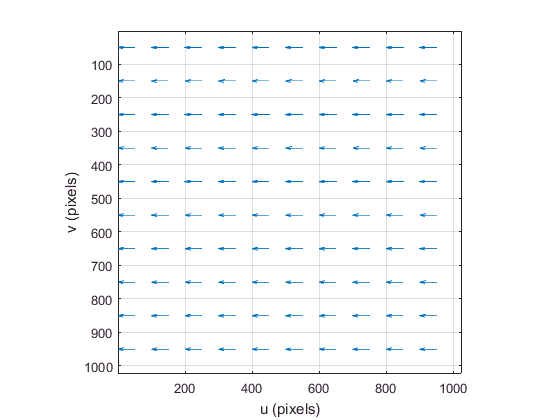


clf
cam.flowfield([1 0 0 0 0 0]);

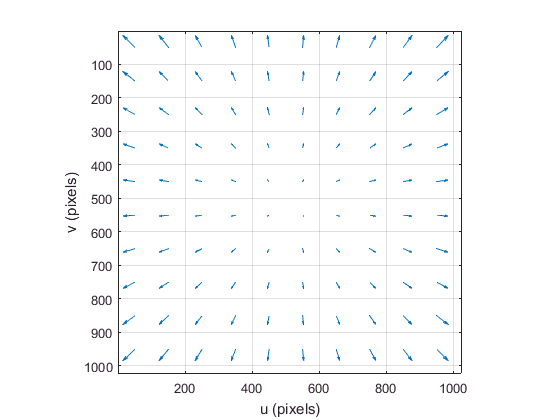

cam.flowfield([0 0 1 0 0 0]);

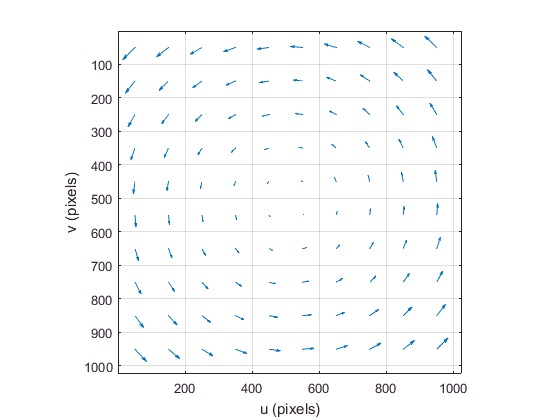

cam.flowfield([0 0 0 0 0 1]);

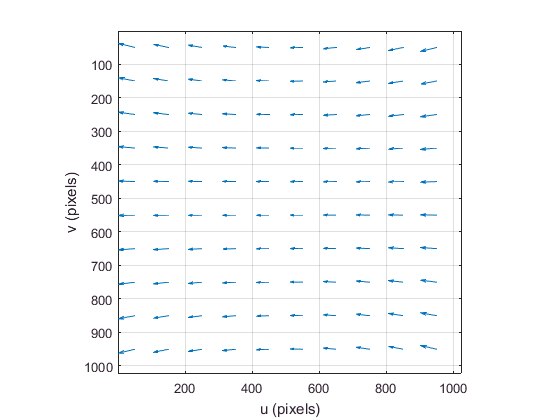

cam.flowfield([0 0 0 0 1 0]);

cam.visjac_p(cam.pp', 1)

ans =  -800.0000         0         0         0 -800.0000         0
         0 -800.0000         0  800.0000         0         0


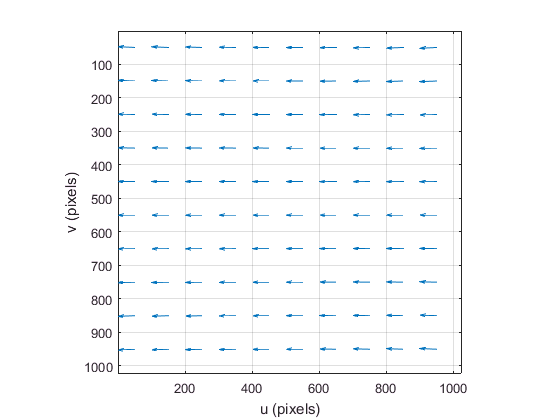

cam.f = 20e-3;
cam.flowfield([0 0 0 0 1 0]);

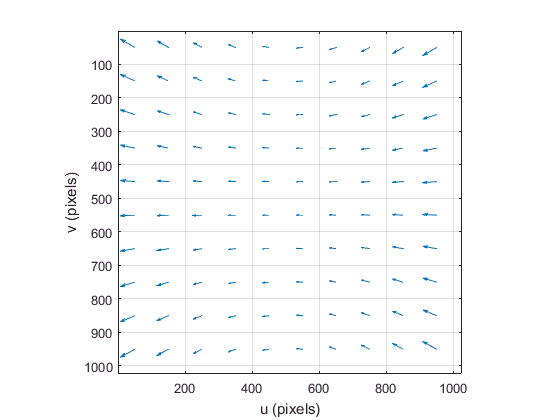

cam.f = 4e-3;
cam.flowfield([0 0 0 0 1 0]);

J = cam.visjac_p(cam.pp', 1);
null(J)

ans =          0         0   -0.7071         0
         0    0.7071         0         0
    1.0000         0         0         0
         0    0.7071         0         0
         0         0    0.7071         0
         0         0         0    1.0000


15.2.2 Controllling feature motion

cam = CentralCamera('default');

principal point not specified, setting it to centre of image plane


P = mkgrid(2, 0.5, 'pose', SE3(0, 0, 3));
pd = bsxfun(@plus, 200*[-1 -1 1 1; -1 1 1 -1], cam.pp')

pd =    312   312   712   712
   312   712   712   312


creating new figure for camera


h =   Axes with properties:

             XLim: [0 1024]
             YLim: [0 1024]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


make axes


p =   445.3333  445.3333  578.6667  578.6667
  445.3333  578.6667  578.6667  445.3333


T_C = SE3(0, 0, 0);
p = cam.plot(P, 'pose', T_C)

e = pd - p

e =  -133.3333 -133.3333  133.3333  133.3333
 -133.3333  133.3333  133.3333 -133.3333


J = cam.visjac_p(p, 1)

J =  -800.0000         0  -66.6667    5.5556 -805.5556  -66.6667
         0 -800.0000  -66.6667  805.5556   -5.5556   66.6667
 -800.0000         0  -66.6667   -5.5556 -805.5556   66.6667
         0 -800.0000   66.6667  805.5556    5.5556   66.6667
 -800.0000         0   66.6667    5.5556 -805.5556   66.6667
         0 -800.0000   66.6667  805.5556   -5.5556  -66.6667
 -800.0000         0   66.6667   -5.5556 -805.5556  -66.6667
         0 -800.0000  -66.6667  805.5556    5.5556  -66.6667


lambda = 0.05;
v = lambda * pinv(J) * e(:)

v =    -0.0000
    0.0000
    0.1000
    0.0000
    0.0000
   -0.0000


T_C = T_C .* SE3.delta(v);
T_C0 = SE3(1, 1, -3)*SE3.Rx(0.6)

 

T_C0 = 
         1         0         0         1
         0    0.8253   -0.5646         1
         0    0.5646    0.8253        -3
         0         0         0         1


ibvs = IBVS(cam, 'pose0', T_C0, 'pstar', pd)

 
ibvs = 
Visual servo object: camera=default
   iterations, 0 history
  P= -0.25       -0.25        0.25        0.25              
     -0.25        0.25        0.25       -0.25              
         0           0           0           0              
  C_T0:   t = ( 1,  1,  -3), R = ( 34.3775deg |  1,  0,  0) 


completed on error tolerance


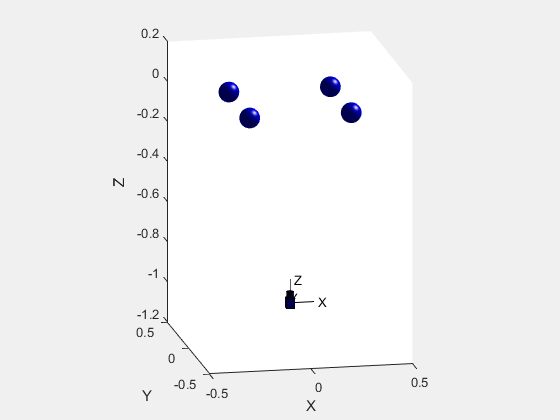

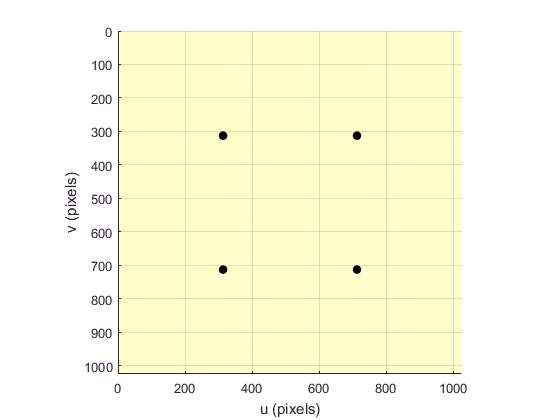

ibvs.run();

ans =   311.9387  312.2290  311.9205  712.0855  711.7881  712.0923  711.7838  312.2360


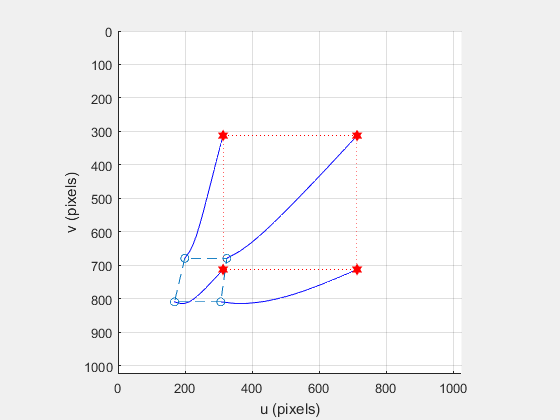

ibvs.plot_p();

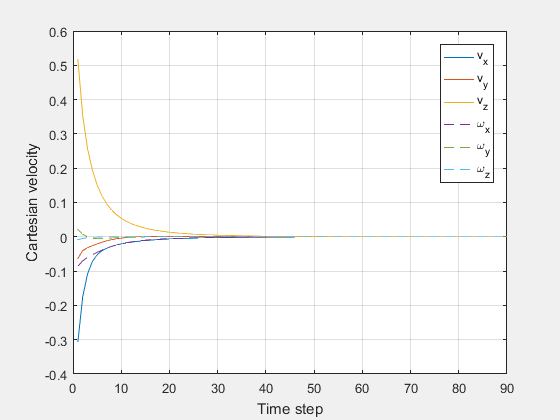

ibvs.plot_vel();

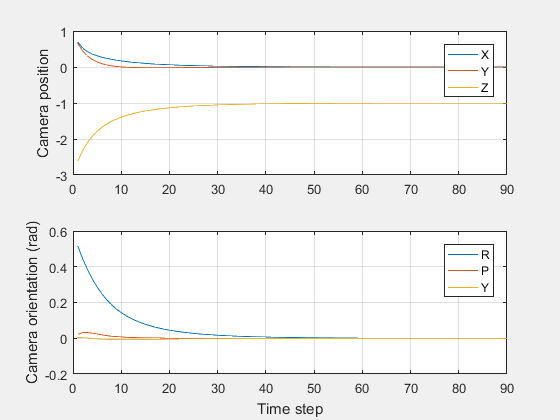

ibvs.plot_camera();

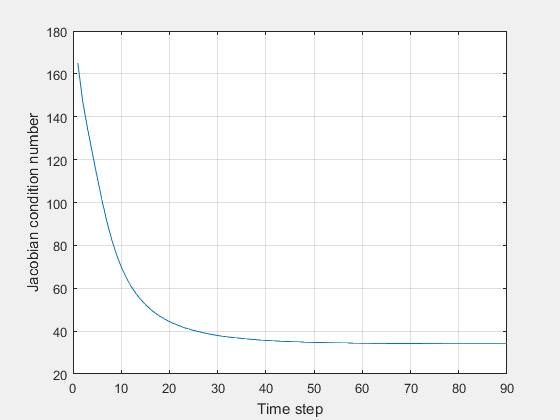

ibvs.plot_jcond();

sl_ibvs

r = sim('sl_ibvs')

principal point not specified, setting it to centre of image plane
 
camera = 
 
name: default [central-perspective]                     
  focal length:   0.008                                 
  pixel size:     (1e-05, 1e-05)                        
  principal pt:   (512, 512)                            
  number pixels:  1024 x 1024                           
  pose:           t = (0, 0, 0), RPY/yxz = (0, 0, 0) deg
 


Error due to multiple causes.

t = r.find('tout');
about(v)
plot(t, v)
p = r.find('yout').signals(1).values;
about(p)
plot2(p)

15.2.3 Estimating Feature Depth

ibvs = IBVS(cam, 'pose0', T_C0, 'pstar', pd, 'depth', 1)

 
ibvs = 
Visual servo object: camera=default
   iterations, 0 history
  P= -0.25       -0.25        0.25        0.25              
     -0.25        0.25        0.25       -0.25              
         0           0           0           0              
  C_T0:   t = ( 1,  1,  -3), R = ( 34.3775deg |  1,  0,  0) 


completed on iteration count


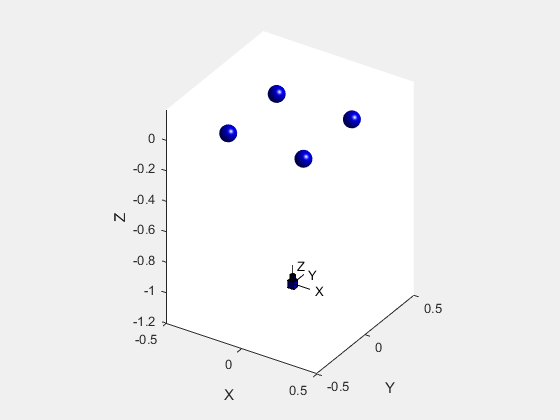

ibvs.run(50)

ans =   306.6093  313.6954  306.5024  701.2699  694.1796  701.3949  694.2031  313.6926


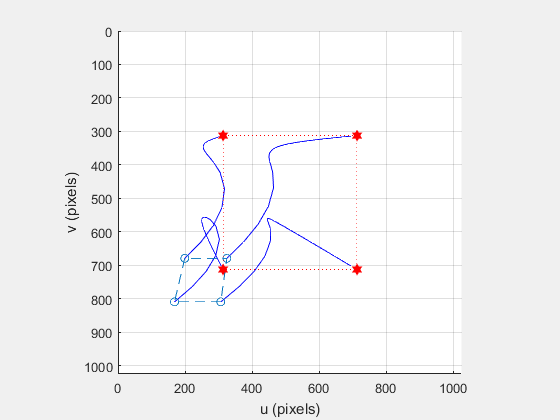

ibvs.plot_p();

ibvs = IBVS(cam, 'pose0', T_C0, 'pstar', pd, 'depth', 10)

 
ibvs = 
Visual servo object: camera=default
   iterations, 0 history
  P= -0.25       -0.25        0.25        0.25              
     -0.25        0.25        0.25       -0.25              
         0           0           0           0              
  C_T0:   t = ( 1,  1,  -3), R = ( 34.3775deg |  1,  0,  0) 


completed on iteration count


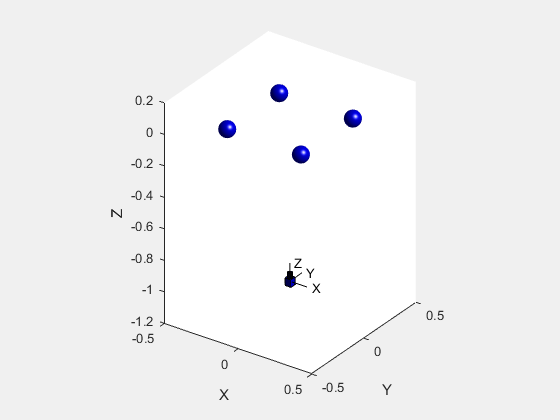

ibvs.run(50)

ans =   316.0393  325.3145  314.5234  725.1270  716.2468  725.5120  714.6449  324.9051


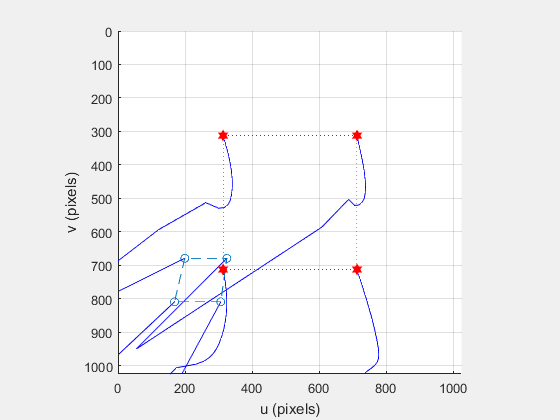

ibvs.plot_p();

ibvs = IBVS(cam, 'pose0', T_C0, 'pstar', pd, 'depthest')

 
ibvs = 
Visual servo object: camera=default
   iterations, 0 history
  P= -0.25       -0.25        0.25        0.25              
     -0.25        0.25        0.25       -0.25              
         0           0           0           0              
  C_T0:   t = ( 1,  1,  -3), R = ( 34.3775deg |  1,  0,  0) 


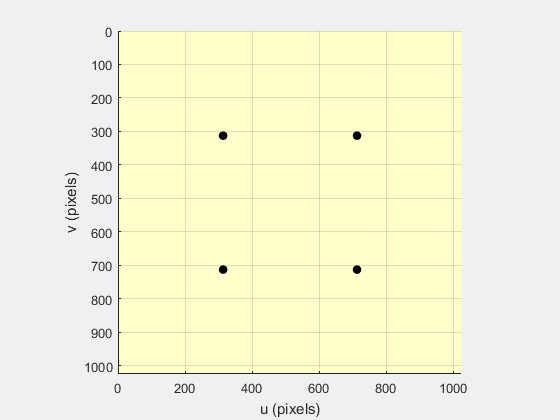

completed on error tolerance


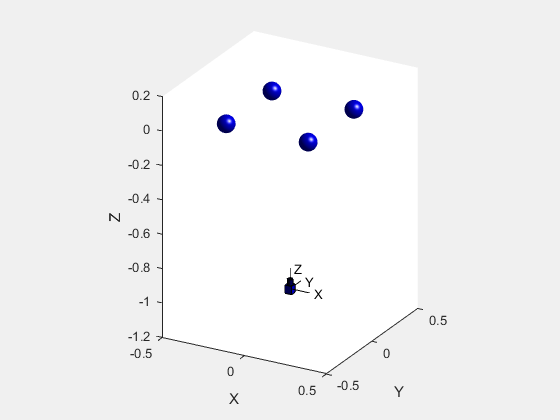

ibvs.run()

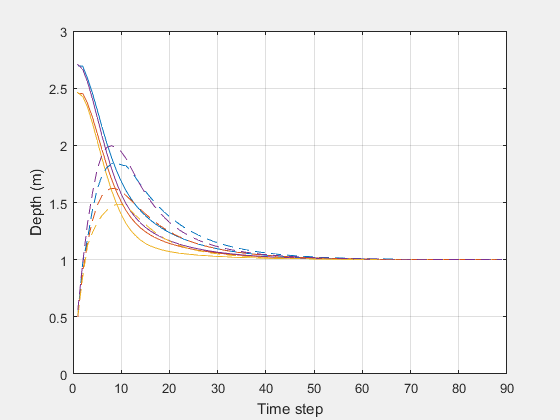

ibvs.plot_z()

ans =   312.1030  312.2999  312.0405  712.0906  711.9135  712.1463  711.8869  312.2801


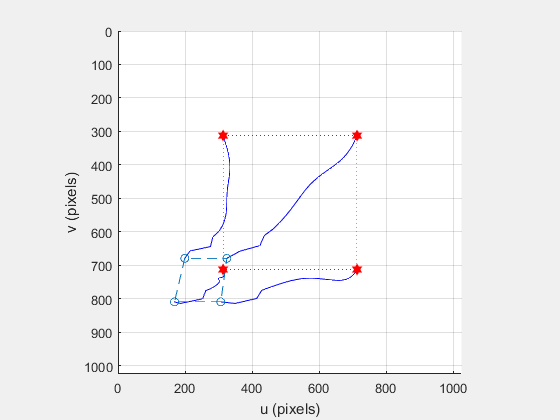

ibvs.plot_p()

15.2.4 Performances issues

completed on iteration count


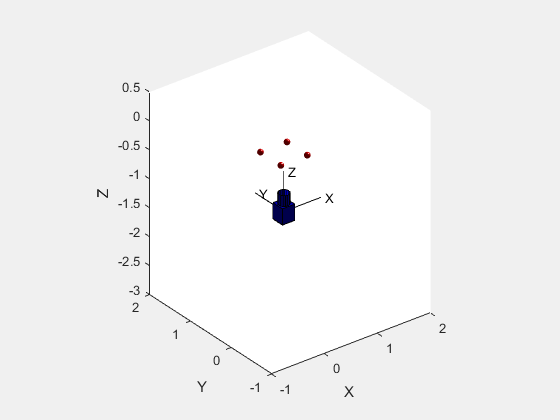

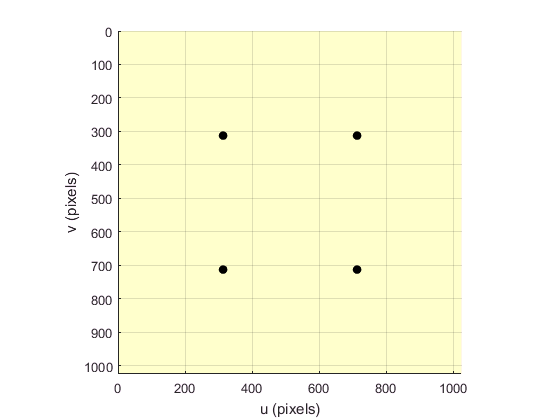

pbvs.T0 = SE3(-2.1, 0, -3) * SE3.Rz(5*pi/4);
pbvs.run()

ans =   312.0894  311.9975  312.0564  711.9695  712.0283  712.0025  712.0614  312.0305


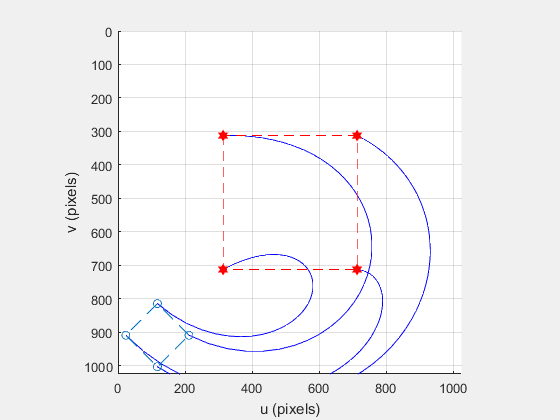

pbvs.plot_p();

ibvs = IBVS(cam, 'pose0', pbvs.T0, 'pstar', pd, 'lambda', 0.002, 'niter', Inf, 'eterm', 0.5)

 
ibvs = 
Visual servo object: camera=default
  Inf iterations, 0 history
  P= -0.25       -0.25        0.25        0.25                 
     -0.25        0.25        0.25       -0.25                 
         0           0           0           0                 
  C_T0:   t = ( -2.1,  0,  -3), R = ( 135deg |  0,  0,  -1)    


completed on iteration count


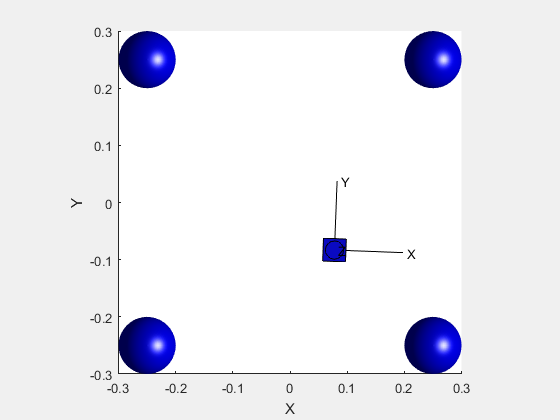

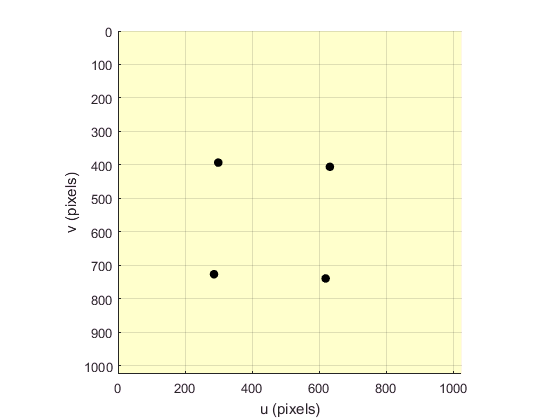

ibvs.run(1000)

ans =   297.6000  392.5896  284.9877  725.9242  618.3223  738.5364  630.9345  405.2019


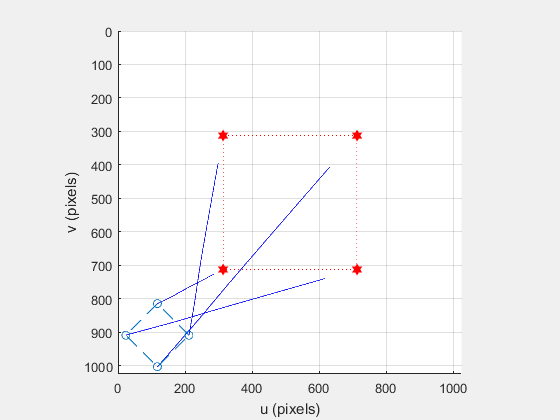

ibvs.plot_p();

completed on error tolerance


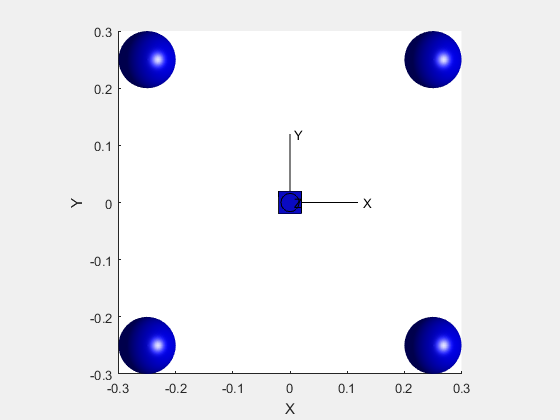

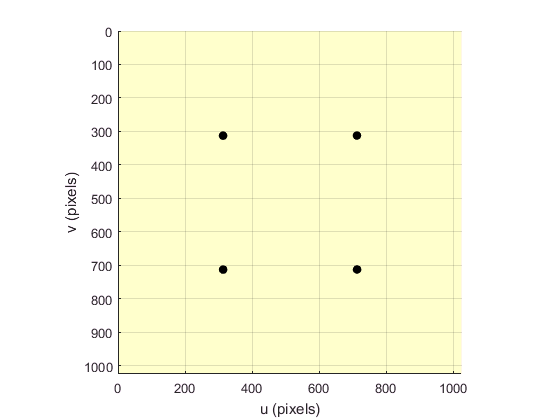

ibvs = IBVS(cam, 'pose0', SE3(0, 0, -1)*SE3.Rz(1), 'pstar', pd);
ibvs.run()

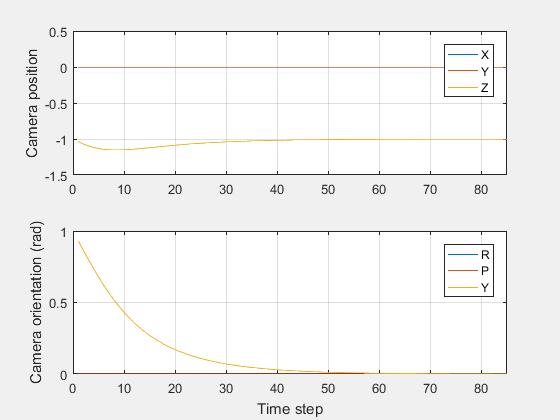

ibvs.plot_p()
ibvs.plot_camera

completed on iteration count


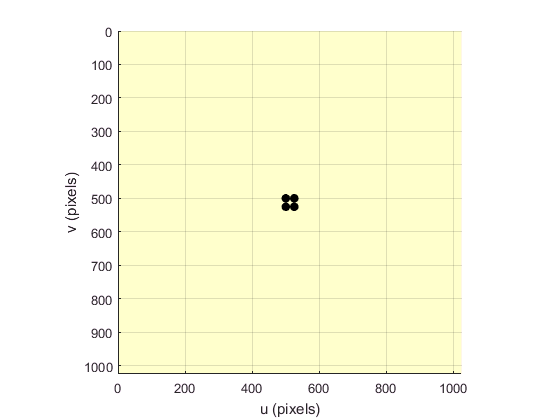

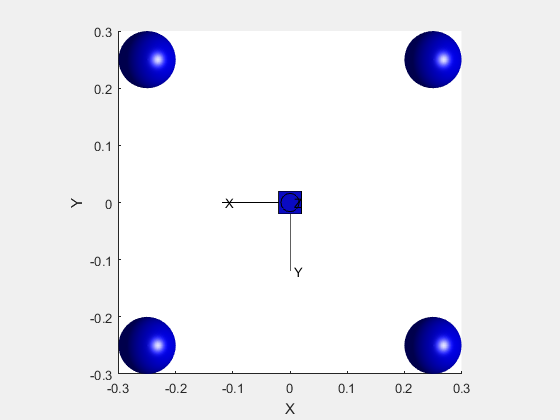

ibvs = IBVS(cam, 'pose0', transl(0, 0, -1)*trotz(pi), 'pstar', pd, 'niter', 10);
ibvs.plot_p()
ibvs.run()

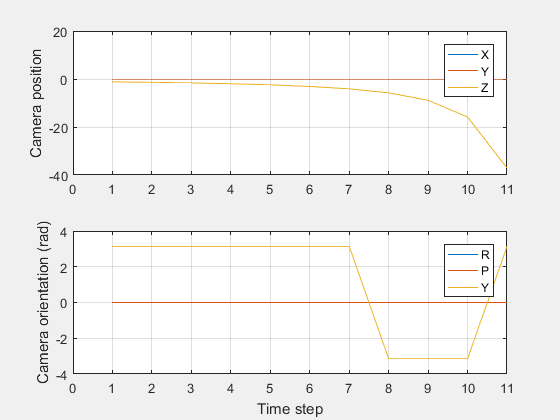

ibvs.plot_camera

15.3 Using other image feature

15.3.1 Line features

cam = CentralCamera('default');

principal point not specified, setting it to centre of image plane


P = circle([0 0 3], 0.5, 'n', 3)

P =     0.5000   -0.2500   -0.2500
         0    0.4330   -0.4330
    3.0000    3.0000    3.0000


cam.project(P);
ibvs = IBVS_l(cam, 'example');

----------------------------
canned example, line-based IBVS with three lines
----------------------------


creating new figure for camera


h =   Axes with properties:

             XLim: [0 1024]
             YLim: [0 1024]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


make axes


completed on error tolerance


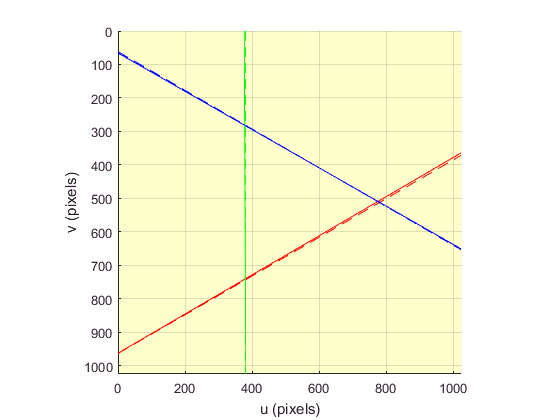

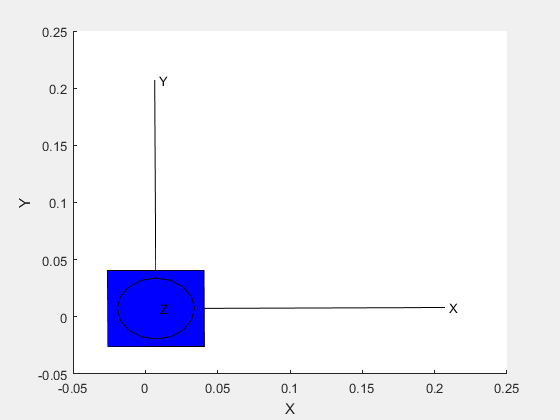

ibvs.run()

ans =   774.4536  508.6494  378.6998  739.6591  376.5165  281.4215


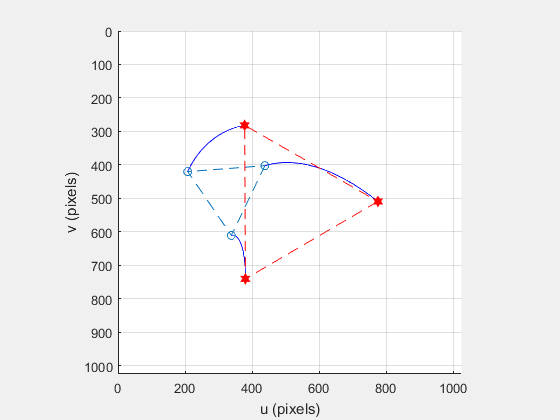

ibvs.plot_p()

15.3.2 Circle feature

P = circle([0 0 3], 0.5, 'n', 10)

P =     0.5000    0.4045    0.1545   -0.1545   -0.4045   -0.5000   -0.4045   -0.1545    0.1545    0.4045
         0    0.2939    0.4755    0.4755    0.2939    0.0000   -0.2939   -0.4755   -0.4755   -0.2939
    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000


Tc = SE3

 

Tc = 
         1         0         0         0
         0         1         0         0
         0         0         1         0
         0         0         0         1


p = cam.project(P, 'pose', Tc)

p =   645.3333  619.8689  553.2023  470.7977  404.1311  378.6667  404.1311  470.7977  553.2023  619.8689
  512.0000  590.3714  638.8075  638.8075  590.3714  512.0000  433.6286  385.1925  385.1925  433.6286


pn = cam.normalized(p)

pn =     0.1667    0.1348    0.0515   -0.0515   -0.1348   -0.1667   -0.1348   -0.0515    0.0515    0.1348
         0    0.0980    0.1585    0.1585    0.0980         0   -0.0980   -0.1585   -0.1585   -0.0980


x = pn(1, :); y = pn(2, :);
a = [y.^2; -2*x.*y; 2*x; 2*y; ones(1, numcols(x))]'

a =          0         0    0.3333         0    1.0000
    0.0096   -0.0264    0.2697    0.1959    1.0000
    0.0251   -0.0163    0.1030    0.3170    1.0000
    0.0251    0.0163   -0.1030    0.3170    1.0000
    0.0096    0.0264   -0.2697    0.1959    1.0000
         0         0   -0.3333         0    1.0000
    0.0096   -0.0264   -0.2697   -0.1959    1.0000
    0.0251   -0.0163   -0.1030   -0.3170    1.0000
    0.0251    0.0163    0.1030   -0.3170    1.0000
    0.0096    0.0264    0.2697   -0.1959    1.0000


b = -(x.^2)';
E = a\b

E =     1.0000
    0.0000
   -0.0000
   -0.0000
   -0.0278


plane = [0 0 1 -3];
J = cam.visjac_e(E, plane)

J =          0         0         0   -0.0000   -0.0000   -0.0000
         0         0         0    0.0000   -0.0000   -0.0000
    0.1667    0.0000   -0.0000   -0.0000    1.0278   -0.0000
    0.0000    0.1667   -0.0000   -1.0278    0.0000    0.0000
   -0.0000   -0.0000   -0.0093    0.0000   -0.0000    0.0000


ibvs = IBVS_e(cam, 'example');

---------------------------------------------------
canned example, ellipse-based IBVS with 10 points
---------------------------------------------------


completed on error tolerance


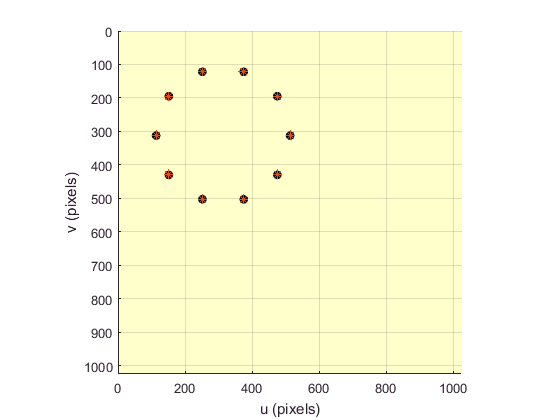

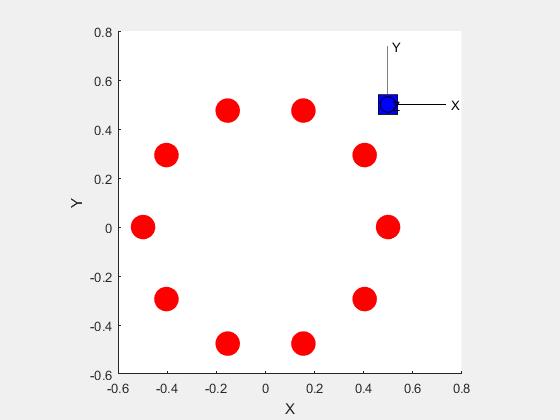

ibvs.run()

ibvs.plot_p()